# Initialization

units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
% add_Li = aLi_12*0.6;
add_Li = 2526*a0;
omegax = 16*pi*2; % trap frequencies 16 Hz
omegay = 74*pi*2;
omegaz = 68*pi*2;

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;
CrossingAngle = 15/180*pi; % cross angle for two ODT beams
D = Wavelength/(2*sin(CrossingAngle/2)); % Lattice period 4 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 250 Hz.

LatticePotential = 50; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 + (omegay/omegax* Y).^2); % function representing the external potential (must have 3 arguments)


xmax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
N = 1000; % number of grid points for coordinate grid


useGPU = false;

if gpuDeviceCount>0 && useGPU
    x = gpuArray.linspace(-xmax,xmax,N);
    y = gpuArray.linspace(-xmax,xmax,N);
    grid = grid2d(x,x);
    a = gpuDevice;
    fprintf('GPU is burning now! %4.2f %% has been used',a.AvailableMemory/a.TotalMemory*100)
else
    grid = grid2d(xmax,N,xmax,N); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)
% task.g = 16*add_Li/(3*R(2)*R(3)); % nonlinear interaction constant


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;

## Stationary state calculation


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);
task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegax*omegay)*omegaz); % nonlinear interaction constant

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step

## switch on lattice for Deltat

Deltat = 600*10^-6/tscale; % total duration for simulation; (600 mico-seconds)
tstep = 20*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

NmaxP = 2; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 

task.UpdatePotential(Vlattice);
task.user_callback = @(x)task.FFTanalysis2D(false,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int

steps_ext = 3.0000e+03


% start simulation
task.solve_split(tstep,steps_int,steps_ext); % run the calculation

Split-step: iter - 2999, mu - 410.582, calc. time - 614.622 sec.; 0 mode Proportion: 1


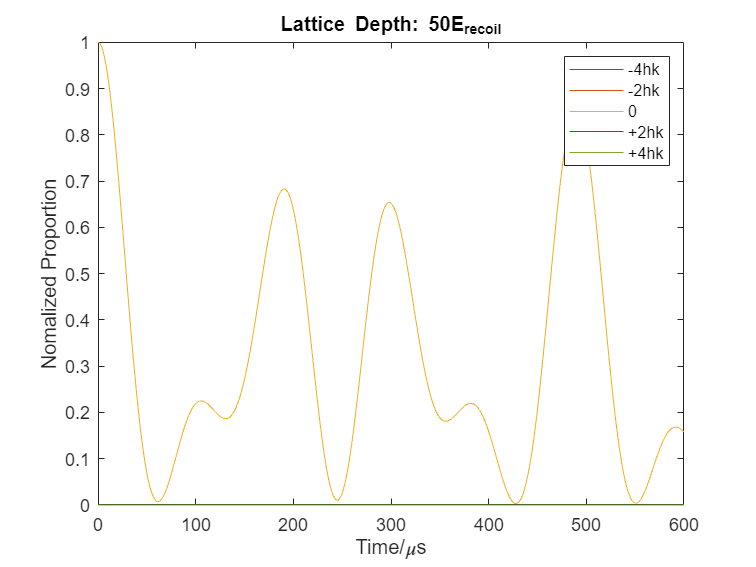


trange = (1:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

## simulate the potential with different interactions 500Er LatticeTime = 3\mus

a_initial =486* a0;
task.UpdatePotential(V);
[phi,mu,R] = task.groundstate_tf_harmonic(a_initial,omegax,omegay,omegaz);
task.init_state = phi;

for add = [486,(1000:1000:4000)]*a0
    % Update the task 
    LatticePotential = 500; % lattice depth in unit of recoil energy
    
    task.reInitialize

    Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.g =sqrt(8*pi)*add/rscale; % nonlinear interaction constant



    Deltat = 3*10^-6/tscale; % total duration for simulation; (3 micro-seconds)
    tstep = 20*10^-9/tscale; % time step for calculation; (2 ns)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    
    % time of flight
    VToF = @(X,Y,Z) 0; 
    task.UpdatePotential(VToF);

    % TOF
    Deltat = 2*10^-6/tscale; % total duration for simulation; (2 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    % Enable the interaction
    Deltat = 10*10^-6/tscale; % total duration for simulation; (10 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.g =sqrt(8*pi)*add/rscale; % nonlinear interaction constant

    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    MomentumDensity = Get_momentumDesity_2D( ...
        task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
    % normalized the momentum density
    MomentumDensity = MomentumDensity ...
        ./max(MomentumDensity(:));
    
    trange = (1:steps_ext)*tstep*steps_int*tscale;
    plot(trange*10^6, MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 

end

Split-step: iter - 15, mu - 3906.621, calc. time - 3.097 sec.; 0 mode Proportion: 1


Split-step: iter - 25, mu - 50.979, calc. time - 2.084 sec.; 0 mode Proportion: 1


Split-step: iter - 75, mu - 51.028, calc. time - 10.323 sec.; 0 mode Proportion: 1


Split-step: iter - 15, mu - 3912.017, calc. time - 3.096 sec.; 0 mode Proportion: 1


Split-step: iter - 25, mu - 56.379, calc. time - 2.080 sec.; 0 mode Proportion: 1


Split-step: iter - 75, mu - 56.479, calc. time - 10.322 sec.; 0 mode Proportion: 1


Split-step: iter - 15, mu - 3922.517, calc. time - 3.094 sec.; 0 mode Proportion: 1


Split-step: iter - 25, mu - 66.884, calc. time - 2.079 sec.; 0 mode Proportion: 1


Split-step: iter - 75, mu - 67.083, calc. time - 10.329 sec.; 0 mode Proportion: 1


Split-step: iter - 15, mu - 3933.017, calc. time - 3.094 sec.; 0 mode Proportion: 1


Split-step: iter - 25, mu - 77.389, calc. time - 2.084 sec.; 0 mode Proportion: 1


Split-step: iter - 75, mu - 77.687, calc. time - 10.319 sec.; 0 mode Proportion: 1


Split-step: iter - 15, mu - 3943.517, calc. time - 3.100 sec.; 0 mode Proportion: 1


Split-step: iter - 25, mu - 87.894, calc. time - 2.080 sec.; 0 mode Proportion: 1


Split-step: iter - 75, mu - 88.291, calc. time - 10.318 sec.; 0 mode Proportion: 1


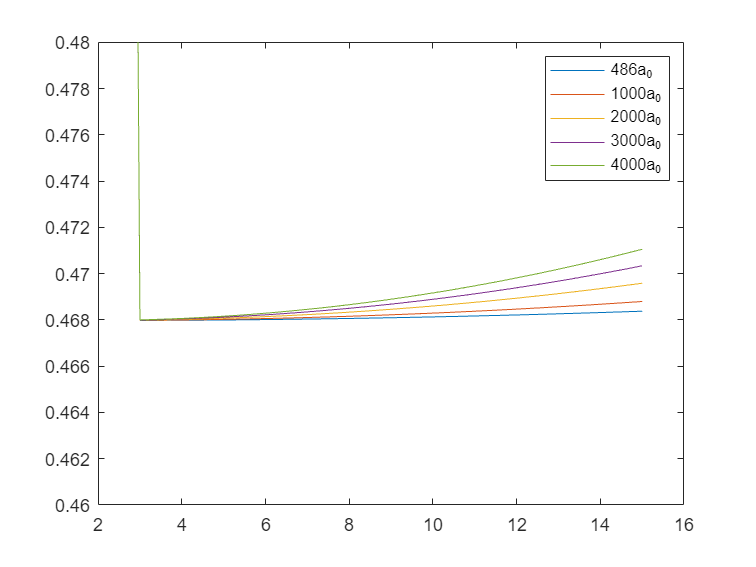

hold off
legend
ylim([0.46 0.48])

## simulate the potential with different interactions 500Er LatticeTime = 8\mus

a_initial =486* a0;
task.UpdatePotential(V);
[phi,mu,R] = task.groundstate_tf_harmonic(a_initial,omegax,omegay,omegaz);
task.init_state = phi;

for add = [486,(1000:1000:4000)]*a0
    % Update the task 
    LatticePotential = 500; % lattice depth in unit of recoil energy
    
    task.reInitialize

    Vlattice = @(X,Y,Z)V(X,Y,Z) + LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.g =sqrt(8*pi)*add/rscale; % nonlinear interaction constant



    Deltat = 8*10^-6/tscale; % total duration for simulation; (3 micro-seconds)
    tstep = 20*10^-9/tscale; % time step for calculation; (2 ns)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    
    % time of flight
    VToF = @(X,Y,Z) 0; 
    task.UpdatePotential(VToF);

    % TOF
    Deltat = 2*10^-6/tscale; % total duration for simulation; (2 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    % Enable the interaction
    Deltat = 10*10^-6/tscale; % total duration for simulation; (10 micro-seconds)
    steps_ext = task.current_iter + Deltat/tstep/steps_int;
    task.g =sqrt(8*pi)*add/rscale; % nonlinear interaction constant

    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    MomentumDensity = Get_momentumDesity_2D( ...
        task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
    % normalized the momentum density
    MomentumDensity = MomentumDensity ...
        ./max(MomentumDensity(:));
    
    trange = (1:steps_ext)*tstep*steps_int*tscale;
    plot(trange*10^6, MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 
    

end

Split-step: iter - 40, mu - 3906.652, calc. time - 8.226 sec.; 0 mode Proportion: 0.998


Split-step: iter - 50, mu - 313.932, calc. time - 2.083 sec.; 0 mode Proportion: 0.998


Split-step: iter - 100, mu - 314.526, calc. time - 10.289 sec.; 0 mode Proportion: 0.998


Split-step: iter - 40, mu - 3912.082, calc. time - 8.224 sec.; 0 mode Proportion: 0.998


Split-step: iter - 50, mu - 319.395, calc. time - 2.076 sec.; 0 mode Proportion: 0.998


Split-step: iter - 100, mu - 320.614, calc. time - 10.285 sec.; 0 mode Proportion: 0.998


Split-step: iter - 40, mu - 3922.646, calc. time - 8.223 sec.; 0 mode Proportion: 0.998


Split-step: iter - 50, mu - 330.022, calc. time - 2.076 sec.; 0 mode Proportion: 0.998


Split-step: iter - 100, mu - 332.451, calc. time - 10.293 sec.; 0 mode Proportion: 0.998


Split-step: iter - 40, mu - 3933.210, calc. time - 8.224 sec.; 0 mode Proportion: 0.998


Split-step: iter - 50, mu - 340.649, calc. time - 2.075 sec.; 0 mode Proportion: 0.998


Split-step: iter - 100, mu - 344.278, calc. time - 10.291 sec.; 0 mode Proportion: 0.998


Split-step: iter - 40, mu - 3943.774, calc. time - 8.221 sec.; 0 mode Proportion: 0.998


Split-step: iter - 50, mu - 351.276, calc. time - 2.076 sec.; 0 mode Proportion: 0.998


Split-step: iter - 100, mu - 356.097, calc. time - 10.286 sec.; 0 mode Proportion: 0.998


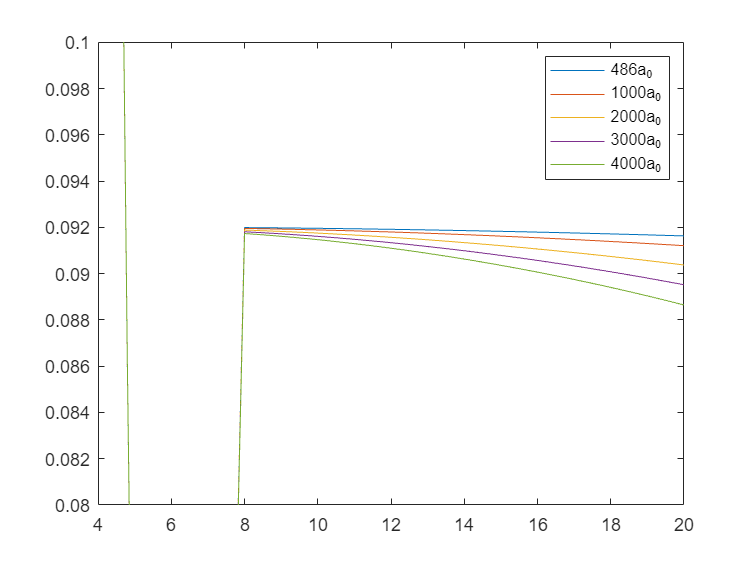

hold off
legend
ylim([0.08 0.1])

## simulate the potential with different interactions 50Er LatticeTime = 8\mus

FifthPeakLoc = [];
add_list = [1,(500:500:2500)]*a0;
for add = add_list
    % Update the task 
    LatticePotential = 50; % lattice depth in unit of recoil energy
    task.UpdatePotential(V);
    [phi,mu,~] = task.groundstate_tf_harmonic(add,omegax,omegay,omegaz);
    task.init_state = phi;

    Vlattice = @(X,Y,Z)LatticePotential*Erecoil/(hbar*omegax)*cos((pi/D)*X*rscale).^2; 
    task.UpdatePotential(Vlattice);
    
    task.reInitialize
    task.g = sqrt(8*pi)*add/rscale*sqrt(omegaz/omegax); % nonlinear interaction constant

    
    Deltat = 800*10^-6/tscale; % total duration for simulation; (800 micro-seconds)
    tstep = 200*10^-9/tscale; % time step for calculation; (20 ns)
    steps_ext = task.current_iter + Deltat/tstep/steps_int
    task.dt = tstep;
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation

    
    MomentumDensity = Get_momentumDesity_2D( ...
        task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
    MomentumDensity = MomentumDensity ...
        ./max(MomentumDensity(:));
    MomentumDensity = MomentumDensity...
        ./ sum(MomentumDensity,2);
    trange = (1:steps_ext)*tstep*steps_int*tscale;

    plot(trange*10^6, MomentumDensity(:,NmaxP+1)' ...
        ,'DisplayName',[num2str(add/a0),'a_0'])
    hold on 
    [~,peakLoc] = findpeaks( MomentumDensity(:,NmaxP+1)');

    FifthPeakLoc = [FifthPeakLoc,trange(peakLoc(5))];
    task.saveTask('_U0',num2str(LatticePotential)...
                    ,'_add',num2str(add/a0))
end

steps_ext = 400.0000

Split-step: iter - 399, mu - 416.427, calc. time - 96.526 sec.; 0 mode Proportion: 0.421


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add1'

steps_ext = 400.0000

Split-step: iter - 399, mu - 403.519, calc. time - 96.409 sec.; 0 mode Proportion: 0.679


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add500'

steps_ext = 400.0000

Split-step: iter - 399, mu - 408.879, calc. time - 96.055 sec.; 0 mode Proportion: 0.715


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add1000'

steps_ext = 400.0000

Split-step: iter - 399, mu - 413.627, calc. time - 95.985 sec.; 0 mode Proportion: 0.68


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add1500'

steps_ext = 400.0000

Split-step: iter - 399, mu - 417.953, calc. time - 96.038 sec.; 0 mode Proportion: 0.595


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add2000'

steps_ext = 400.0000

Split-step: iter - 399, mu - 421.576, calc. time - 105.491 sec.; 0 mode Proportion: 0.483


ans = 'Successfully saved in ./Data/D4_2D_Tstep200_Tnow798_U050_add2500'

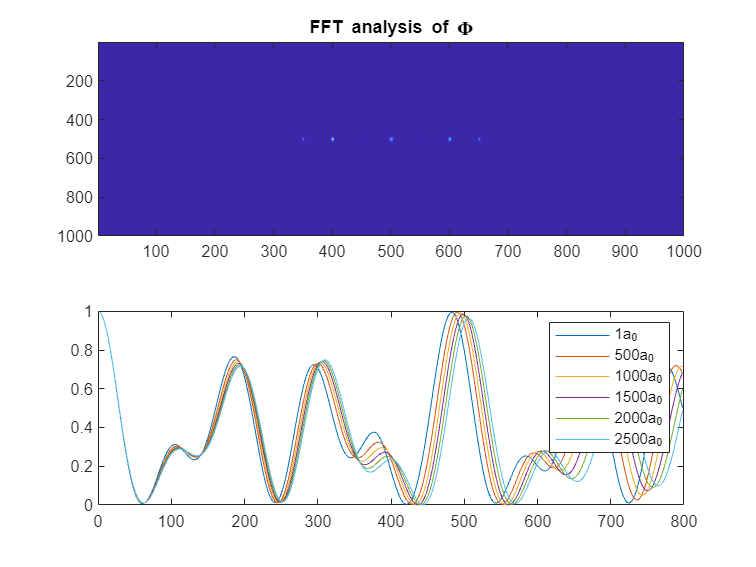

hold off
legend

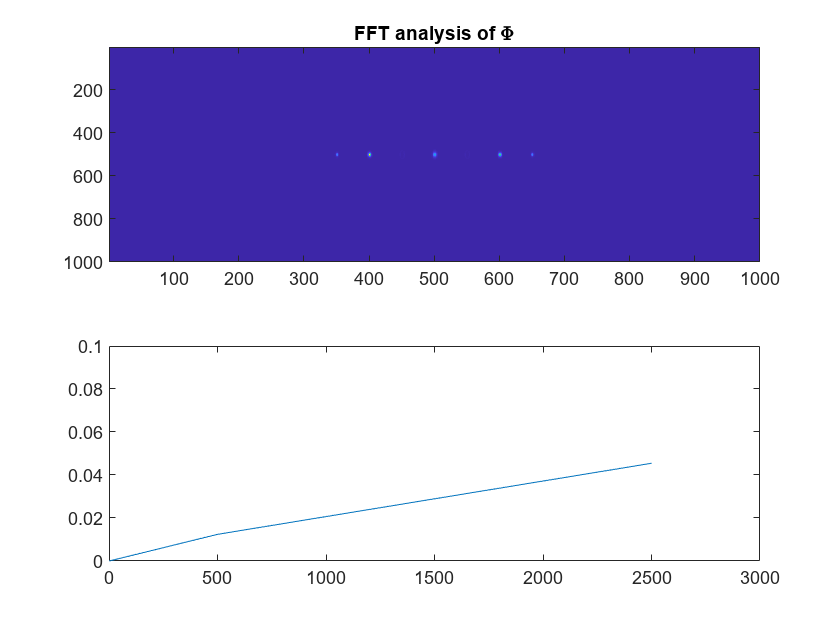

rSlowingPara = FifthPeakLoc/FifthPeakLoc(1)-1;
plot(add_list/a0,rSlowingPara);
xlim([0 3000])

ylim([0 0.1])

Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 8.8709